# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

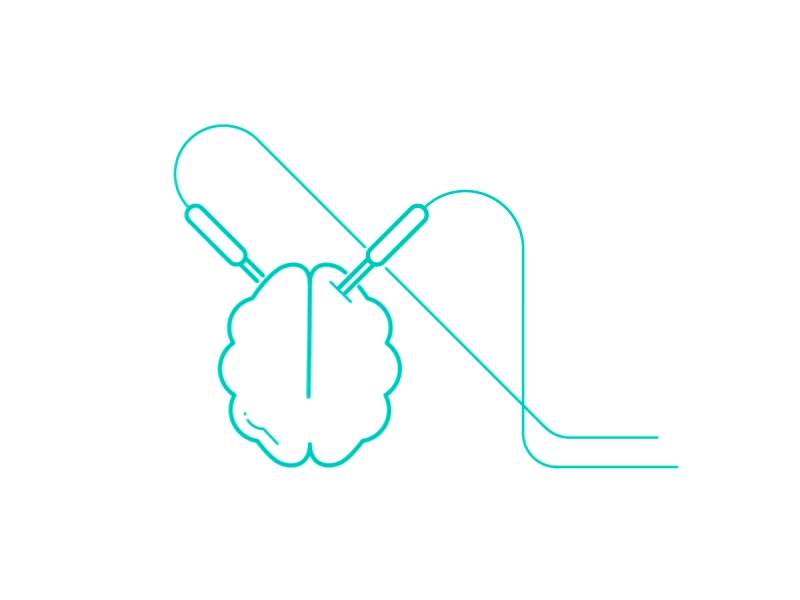

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Luke\Simon\RawData_All'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 4 ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Folder.Version     = ['C:\Users\User\Desktop\Luke\Simon\ProcessedDataTest'];        % Output Folder Directory

## 1. Trial Definitions 

Deci.DT.Type = 'Simon_Polymerase';
Deci.DT.Starts     = {17};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {18};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[14 15] [16 45 46 19] [300 400] [37 38] [31 34] [23 24]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [12 30 22];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq                                                               % Time of Interest, be sure to include larger window for freq

Deci.DT.Block.Markers   = {40};
Deci.DT.Block.Bisect = true;

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.5 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.bpfreq = [1 30];

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.RT.minlength = 200;
Deci.Art.RT.locks = [2 1];

## 4. Analysis

if Deci.Step == 4
Deci.DT.Markers    = {[14 15] [300 400] [31 34] [1014 1015] [1300 1400] [1031 1034]};

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.Locks         = [1 2 3];                                                          % Which Lock to Analyze        
Deci.Analysis.LocksTitle    = {'Stim Onset' 'Rsp Onset' 'Fdb Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.DownSample    = 500;  
Deci.Analysis.Toi = [-.5 1.5];
Deci.Analysis.Toilim = [-2 3];


Deci.Analysis.Conditions    = {[14 15]};
Deci.Analysis.CondTitle     = {'All Stimulus'}; 
Deci.Analysis.Version = [Deci.Folder.Version];

Deci.Analysis.HemifieldFlip.do = true;
Deci.Analysis.HemifieldFlip.Markers = [15 14];

Deci.Analysis.ERP.do  = true;

%Analysistypes = {'Exp_Analysis1', 'Exp_Analysis2'}; 
%    for AnalysisLocks = Analysistypes
 %       eval(AnalysisLocks{1})
        Deci_Backend(Deci);
 %   end
end

Running Deci for 1 subjects
 
----------------------
Starting Analyzor for Subject #1: Simon_EEGTest1_001PS
 
Downsampling Applied
HemifieldFlip Applied
 
---Starting Condition #1: Left---
 
ignoring 8 trials with missing locks
Applying Artifact Rejection
Final trial count is 177
 
---Starting Lock #1: Stim Onset---
 
 
---Starting Lock #2: Rsp Onset---
 
 
---Starting Lock #3: Fdb Onset---
 
 
---Starting Condition #2: Right---
 
ignoring 13 trials with missing locks
Applying Artifact Rejection
Final trial count is 191
 
---Starting Lock #1: Stim Onset---
 
 
---Starting Lock #2: Rsp Onset---
 
 
---Starting Lock #3: Fdb Onset---
 
Analyzed for Simon_EEGTest1_001PS Time: 146.342
Full Analysis Time:146.345


## 5. Plotting

if Deci.Step == 5

    Deci.Plot.Version = [Deci.Analysis.Version];
    Deci.Plot.Figures      = [true true ];
    Deci.Plot.Math         = {'x2 - x1' 'x2 + x1'};           % Condition Math done after Bsl, Condition Indexes are appended on.
    Deci.Plot.Draw         = {[1 2] [3]};                   % Cell array of Condition Index for each figure
    
    Deci.Plot.Title        = {'All Trials' 'Incorrect - Correct'};          % Title for each figure
    Deci.Plot.Subtitle     = {{'Correct' 'Incorrect'} {'Inc - Cor'}};     % Cell array of strings of subtitles for each Condition

    
    Simon_Cor;
    
    %Deci.Run.Freq =false;
    Deci.Run.ERP =false;
    Deci.Run.Extra = false;
    
    Deci.Plot.BslRef = 'Stim Onset';
    Deci.Plot.Lock =   'Stim Onset';
    
    if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
        Deci.Plot.Bsl     = [-.5 -.2];
    else
        Deci.Plot.Bsl     = [-.2 0];
    end
    
    Deci.Plot.GrandAverage = true;
    
    Deci.Plot.Freq.Topo.do    =false;
    Deci.Plot.Freq.Topo.Toi     = [.2 .5];                   % Time of Interest
    Deci.Plot.Freq.Topo.Channel = [{'FCz' 'Cz' 'Fz'}];                   % Channel of Interest
    
    Deci.Plot.Wire.do    =false;
    Deci.Plot.Wire.Toi     = [-.5 0];                   % Time of Interest
    Deci.Plot.Wire.Channel = [{'PO7' 'PO8'}];              % Channel of Interest
    
    Deci.Plot.Bar.do    =false;
    Deci.Plot.Bar.Toi     = [-.5 -.4];                   % Time of Interest
    Deci.Plot.Bar.Channel =  [{'PO7' 'PO8'}];            % Channel of Interest

    Deci.Plot.Stat.do = true; % Will only work if for large subject pools
    if Deci.Plot.Stat.do
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
    end
    
    Deci_Backend(Deci);
end

